**Course:                **Industrielle & Medizinische Bildverarbeitung

**Insitute:                **Salzburg University of Applied Sciences  

**Author:                 **Niko Jozic 

**Departement:       **Information Technology & System-Management

# 4.1.b

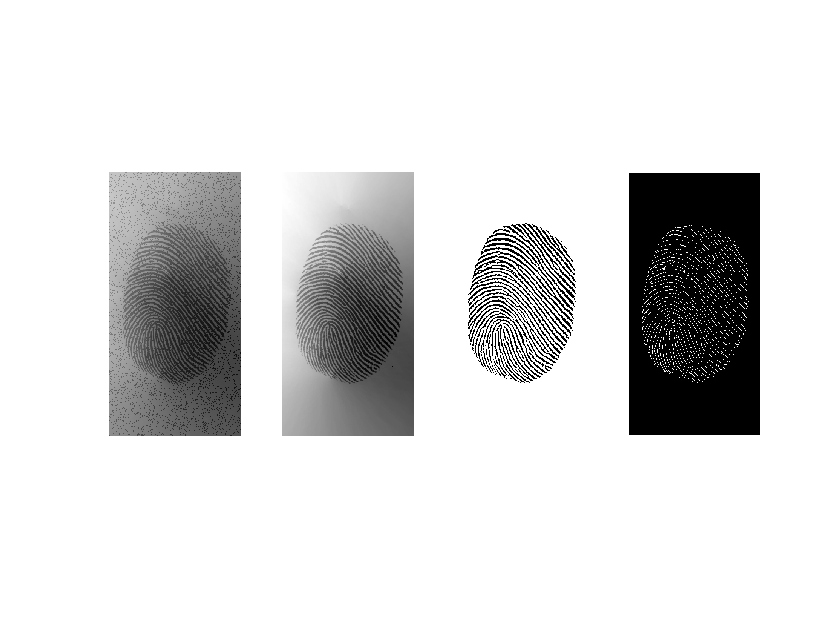

clc, clear variables, close all, format compact;

img = imread('fingerprint.png');

subplot(141);
imshow(img);

subplot(142);
se = strel('disk',1);
% se = offsetstrel('ball',1,5);
BW = imcomplement(img);
img_erode = imerode(BW,se);
img_dilate = imdilate(img_erode,se);
BW = imcomplement(img_dilate);
imshow(BW,[]);

subplot(143)
BW = imcomplement(BW);
% BW = imbinarize(BW, 'adaptive');
seg_img = MyAdaptiveThresholding(BW,4,0.94);
imshow(seg_img,[])

subplot(144)
BW2 = imcomplement(seg_img);
BW3 = bwmorph(BW2,'thin',inf);
imshow(BW3,[])

# 4.1.c

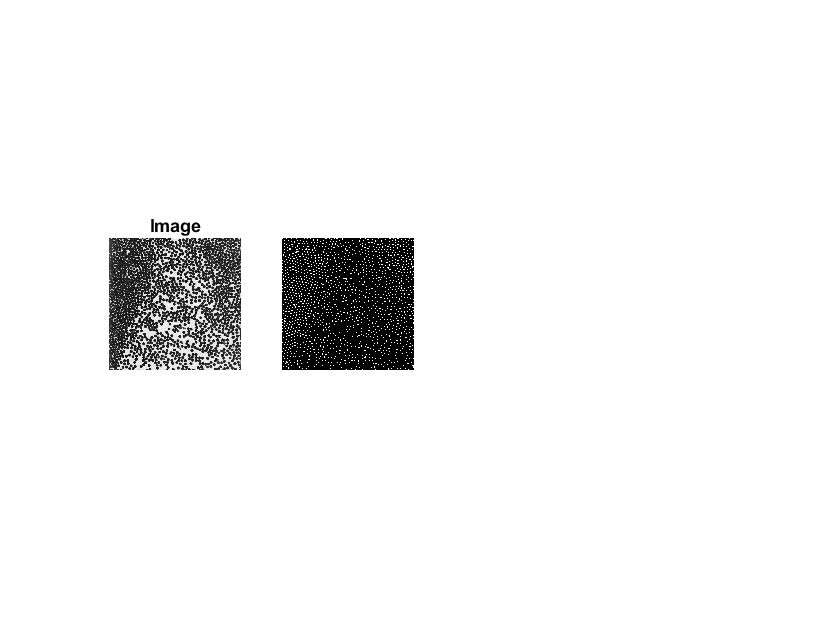

clc, clear variables, close all, format compact;

img = imread('balls.png');

subplot(141);
imshow(img,[]);
title('Image');

subplot(142);
img_gray = rgb2gray(img);
level = graythresh(img_gray);
BW = imbinarize(img_gray,level);
BW2 = imcomplement(BW);
se = strel('disk',5);
BW3 = imerode(BW2,se);
[L,N] = bwlabel(BW3,4);
imshow(BW3,[]);


fprintf("The counting says: %g Balls\n",N);

The counting says: 1672 Balls
